# Spring-Mass Simulator 2021

#### A. Rodriguez-Gonzalez

- This is a simulator for the 1-D spring-mass system illustrated below. The positions of the masses are defined globally on the 1-D coordinate system $x$ in meters, with equilibrium positions $x_i = 0$ defined for each mass at $x=1$, $x=2$, and $x=3$ respectively. All spring constants are $k = 1$ newton per meter and all masses are $m = 1$ kilogram.

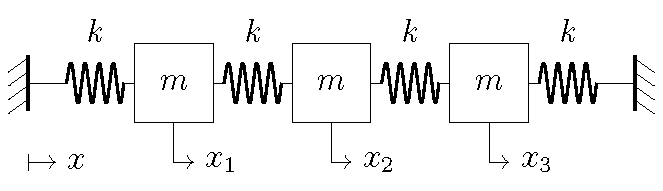

- Provide initial conditions for this spring-mass system and watch the oscillations occur in real-time by pressing the button! (Allow about half a second for the simulation to stabilize and display time-accurate results.)

- The model does not account for collisions, so masses may pass through each other for large initial displacements or velocities.

- Did you know you can put emoji into MATLAB Live Scripts? 🤯 I feel like liberal emoji usage or a cringy TikTok would make me more relatable to Gen Z.

- "This 🖥️📈 is the 💣 and will help you 👨‍🏫/👩‍🏫 yourself about normal modes and vibrations!" (Do my teaching evaluations go up now?)

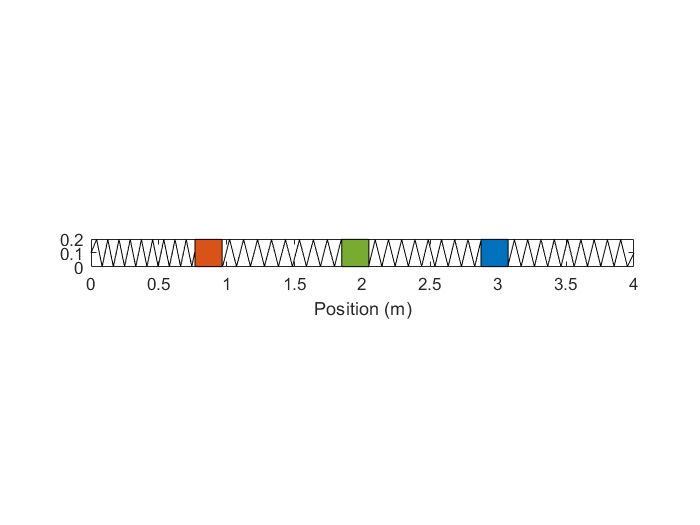

% Delete variables and graphs in workspace.
clear
close all
% Define initial conditions.
x01 =0;
x02 =0;
x03 =0;
v01 =0.9;
v02 =0;
v03 =0;
% Define times from zero to thirty seconds.
t = linspace(0,30,10000);
% Solve the ODE associated with this spring-mass system.
[t,x] = ode45(@springsrhs,t,[x01; x02; x03; v01; v02; v03]);
 
% Initialize internal clock.
[xs1,ys1] = spring(0,0.1,x01+1,0.1,10,1,0.1);
[xs3,ys3] = spring(x02+2,0.1,x03+3,0.1,10,1,0.1);
[xs2,ys2] = spring(x01+1,0.1,x02+2,0.1,10,1,0.1);
[xs4,ys4] = spring(x03+3,0.1,4,0.1,10,1,0.1);
h = plot(xs1,ys1,xs2,ys2,xs3,ys3,xs4,ys4,'Color','k');
a = rectangle('Position',[x01-0.1 + 1,0,0.2,0.2],'FaceColor',[0.8500, 0.3250, 0.0980]);
b = rectangle('Position',[x02-0.1 + 2,0,0.2,0.2],'FaceColor',[0.4660, 0.6740, 0.1880]);
c = rectangle('Position',[x03-0.1 + 3,0,0.2,0.2],'FaceColor',[0, 0.4470, 0.7410]);
axis equal
axis([0 4 0 0.2])
box on
xlabel('Position (m)')

tic
tr = toc;
while tr <= max(t) - 1
    % Return current clock value. If clock time is larger than maximum time
    % in ODE, finish simulation.
    tr = toc;
    % Plot springs and masses at the simulation time corresponding to the
    % clock time calculated above.
    hold on
    x1t = interp1(t,x(:,1),tr);
    x2t = interp1(t,x(:,2),tr);
    x3t = interp1(t,x(:,3),tr);
    [xs1,ys1] = spring(0,0.1,x1t+1,0.1,10,1,0.1);
    [xs3,ys3] = spring(x2t+2,0.1,x3t+3,0.1,10,1,0.1);
    [xs2,ys2] = spring(x1t+1,0.1,x2t+2,0.1,10,1,0.1);
    [xs4,ys4] = spring(x3t+3,0.1,4,0.1,10,1,0.1);
    h(1).XData = xs1;
    h(2).XData = xs2;
    h(3).XData = xs3;
    h(4).XData = xs4;
    h(1).YData = ys1;
    h(2).YData = ys2;
    h(3).YData = ys3;
    h(4).YData = ys4;
    a.Position = [x1t-0.1 + 1,0,0.2,0.2];
    b.Position = [x2t-0.1 + 2,0,0.2,0.2];
    c.Position = [x3t-0.1 + 3,0,0.2,0.2];
    drawnow
end
close all

## Activities

- Based on the symmetry of the problem, try to guess a normal mode of this system, and then input the corresponding initial conditions to see if your guess is actually a normal mode. (Remember, if the masses don't oscillate with the same frequency, they're not normal modes!)

- Input initial conditions that you *feel* would lead to a normal mode but don't. Try to develop some intuition about why those aren't normal modes by comparing the simulation to your intuitive predictions.

- Find the equations of motion in matrix form for this spring-mass system, and using the normal mode assumption, calculate what the eigenvectors & eigenvalues are. Use these to define each normal mode and its associated frequency.

- For normal modes you find by whatever method, calculate their frequency and period. Use a timer to measure the period of the normal mode you observe in the simulation, and compare that to what you predicted. (They should agree fairly well unless the simulation appears extremely laggy.)

function dxdt = springsrhs(t,x) 
% Equations of motion for spring-mass system described above in first-order
% form.
    dxdt(1) = x(4);
    dxdt(2) = x(5);
    dxdt(3) = x(6);
    dxdt(4) = -x(1) + (x(2) - x(1)) - 0*x(4);
    dxdt(5) = (x(1) - x(2)) + (x(3) - x(2)) - 0*x(5);
    dxdt(6) = -x(3) + (x(2) - x(3)) - 0*x(6);
    dxdt = dxdt';
end

function [xs,ys] = spring(xa,ya,xb,yb,varargin)
% SPRING         Calculates the position of a 2D spring
%    [XS YS] = SPRING(XA,YA,XB,YB,NE,A,R0) calculates the position of
%    points XS, YS of a spring with ends in (XA,YA) and (XB,YB), number
%    of coils equal to NE, natural length A, and natural radius R0. 
%    Useful for mass-spring oscillation animations.
% USAGE: in a first call in your code, call it with the full parameters.
% Then, only you have to give it the coordinates of the ends.
% EXAMPLE:
% xa = 0; ya = 0; xb = 2; yb = 2; ne = 10; a = 1; ro = 0.1;
% [xs,ys] = spring(xa,ya,xb,yb,ne,a,ro); plot(xs,ys,'LineWidth',2)
%...
% [xs,ys]=spring(xa,ya,xb,yb); plot(xs,ys,'LineWidth',2)
%
%   Made by:            Gustavo Morales   UC  08-17-09 gmorales@uc.edu.ve
%
    persistent ne Li_2 ei b
    if nargin > 4 % calculating some fixed spring parameters only once time
        [ne, a, r0] = varargin{1:3};                  % ne: number of coils - a = natural length - r0 = natural radius
        Li_2 =  (a/(4*ne))^2 + r0^2;                % (large of a quarter of coil)^2
        ei = 0:(2*ne+1);                            % vector of longitudinal positions
        j = 0:2*ne-1; b = [0 (-ones(1,2*ne)).^j 0]; % vector of transversal positions
    end
    R = [xb yb] - [xa ya]; mod_R = norm(R); % relative position between "end_B" and "end_A"
    L_2 = (mod_R/(4*ne))^2; % (actual longitudinal extensión of a coil )^2
    if L_2 > Li_2
       error('Spring:TooEnlargement', ...
       'Initial conditions cause pulling the spring beyond its maximum large. \n Try reducing these conditions.')
    else
        r = sqrt(Li_2 - L_2);   %actual radius
    end
    c = r*b;    % vector of transversal positions
    u1 = R/mod_R; u2 = [-u1(2) u1(1)]; % unitary longitudinal and transversal vectors 
    xs = xa + u1(1)*(mod_R/(2*ne+1)).*ei + u2(1)*c; % horizontal coordinates
    ys = ya + u1(2)*(mod_R/(2*ne+1)).*ei + u2(2)*c; % vertical coordinates
end